# EEG Data Preprocessing

## Loading Dataset

% Initialize Data Parameters

fs = 256; % sample rate in Hz
testNodes = ["Cz","F4"];
H_CzF4 = EEGData(FC(1:6),testNodes,fs);
A_CzF4 = EEGData(FADHD(1:6),testNodes,fs);

Subjectnum = 1;
Channel = 1;

H_Test1 = H_CzF4.Task(1);
A_Test1 = A_CzF4.Task(1);

H_subject = subject(1,1);
A_subject = subject(1,0);

H_subject.Data = H_Test1.getSubjectData(H_subject.Id,"Cz");

A_subject.Data = A_Test1.getSubjectData(A_subject.Id,"Cz");

## Data Filtering

The first step in processing the data    

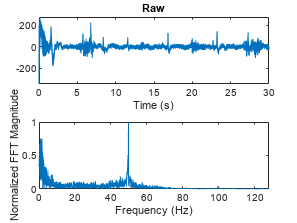

ButterHP = designfilt('highpassiir', ...
    'StopbandFrequency',1, ...
    'PassbandFrequency',2, ...
    'StopbandAttenuation',60, ...
    'PassbandRipple',1, ...
    'SampleRate',256);

%{ 
ButterBP = designfilt('bandpassiir', ...
    'StopbandFrequency1',0.5, ...
    'PassbandFrequency1',2, ...
    'PassbandFrequency2',40, ...
    'StopbandFrequency2',50, ...
    'StopbandAttenuation1',40, ...
    'PassbandRipple',1, ...
    'StopbandAttenuation2',40, ...
    'SampleRate',256);
%}
ButterBS = designfilt('bandstopiir', ...
    'PassbandFrequency1',45, ...
    'StopbandFrequency1',48, ...
    'StopbandFrequency2',52, ...
    'PassbandFrequency2',55, ...
    'PassbandRipple1',1, ...
    'StopbandAttenuation',60, ...
    'PassbandRipple2',1, ...
    'SampleRate',256);
raw = H_subject.Data;
padlen = 256;
padded = [flip(raw(1:padlen)) raw flip(raw(end-padlen+1:end))];


H_HPfiltered = filtfilt(ButterHP,padded);

H_Combofiltered = filtfilt(ButterBS,filtfilt(ButterHP,padded));
H_Combofiltered = H_Combofiltered(padlen+1:end-padlen);
%H_BPfiltered = filtfilt(ButterBP,H_HPfiltered);
%H_BPfiltered =H_BPfiltered(padlen+1:end-padlen);
H_HPfiltered =H_HPfiltered(padlen+1:end-padlen);

len = length(H_subject.Data);
Hz = fs/len*(0:len-1);

signals = {H_HPfiltered; H_Combofiltered; H_subject.Data;};
times = H_Test1.times(1:end-1);
names = ["High","High*Band","Raw"];
for i = 1:numel(signals)
    fsig = abs(fft(signals{i}));
    fsig = fsig/max(fsig);
    
    figure(i);
    subplot(2,1,1);
    plot(times,signals{i});
    xlabel("Time (s)");
    title(names(i));
    subplot(2,1,2);
    plot(Hz,fsig);
    ylabel("Normalized FFT Magnitude");
    xlabel("Frequency (Hz)")
    xlim([0 128])
end